# **Mina Shiri - 40011023 - HW 1**

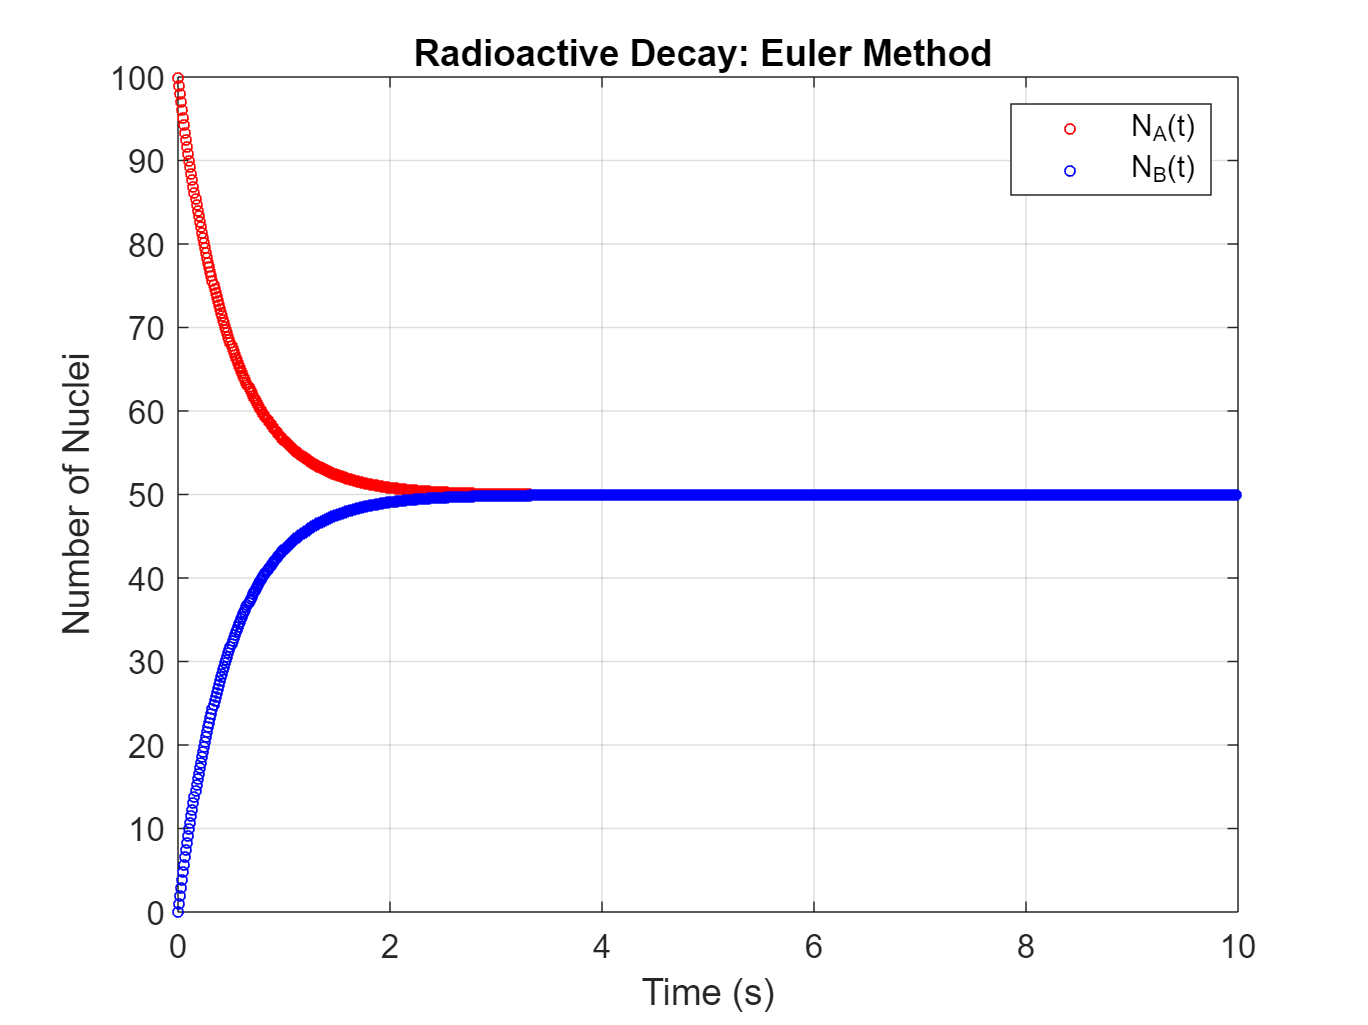

% شرایط اولیه
N_A0 = 100;
N_B0 = 0;

% ثابت زمانی
tau = 1;

% گام زمانی و تعداد گام‌ها
dt = 0.01;
t_final = 10;
steps = t_final / dt;

% پیش‌اختصاص آرایه‌ها
N_A = zeros(steps, 1);
N_B = zeros(steps, 1);
t = zeros(steps, 1);

% مقداردهی اولیه
N_A(1) = N_A0;
N_B(1) = N_B0;
t(1) = 0;

% روش اویلر برای حل عددی
for i = 2:steps
    N_A(i) = N_A(i-1) + dt * (N_B(i-1)/tau - N_A(i-1)/tau);
    N_B(i) = N_B(i-1) + dt * (N_A(i-1)/tau - N_B(i-1)/tau);
    t(i) = t(i-1) + dt;
end

% پاسخ تحلیلی
y_A = 50 * (1 + exp(-2 * t)); 
y_B = 50 * (1 - exp(-2 * t));

% رسم نمودار
figure; 
plot(t, N_A, 'ro', 'MarkerSize', 3); % N_A
hold on; 
plot(t, N_B, 'bo', 'MarkerSize', 3);  % N_B

xlabel('Time (s)'); 
ylabel('Number of Nuclei'); 
legend('N_A(t)', 'N_B(t)'); 
title('Radioactive Decay: Euler Method '); 
grid on;

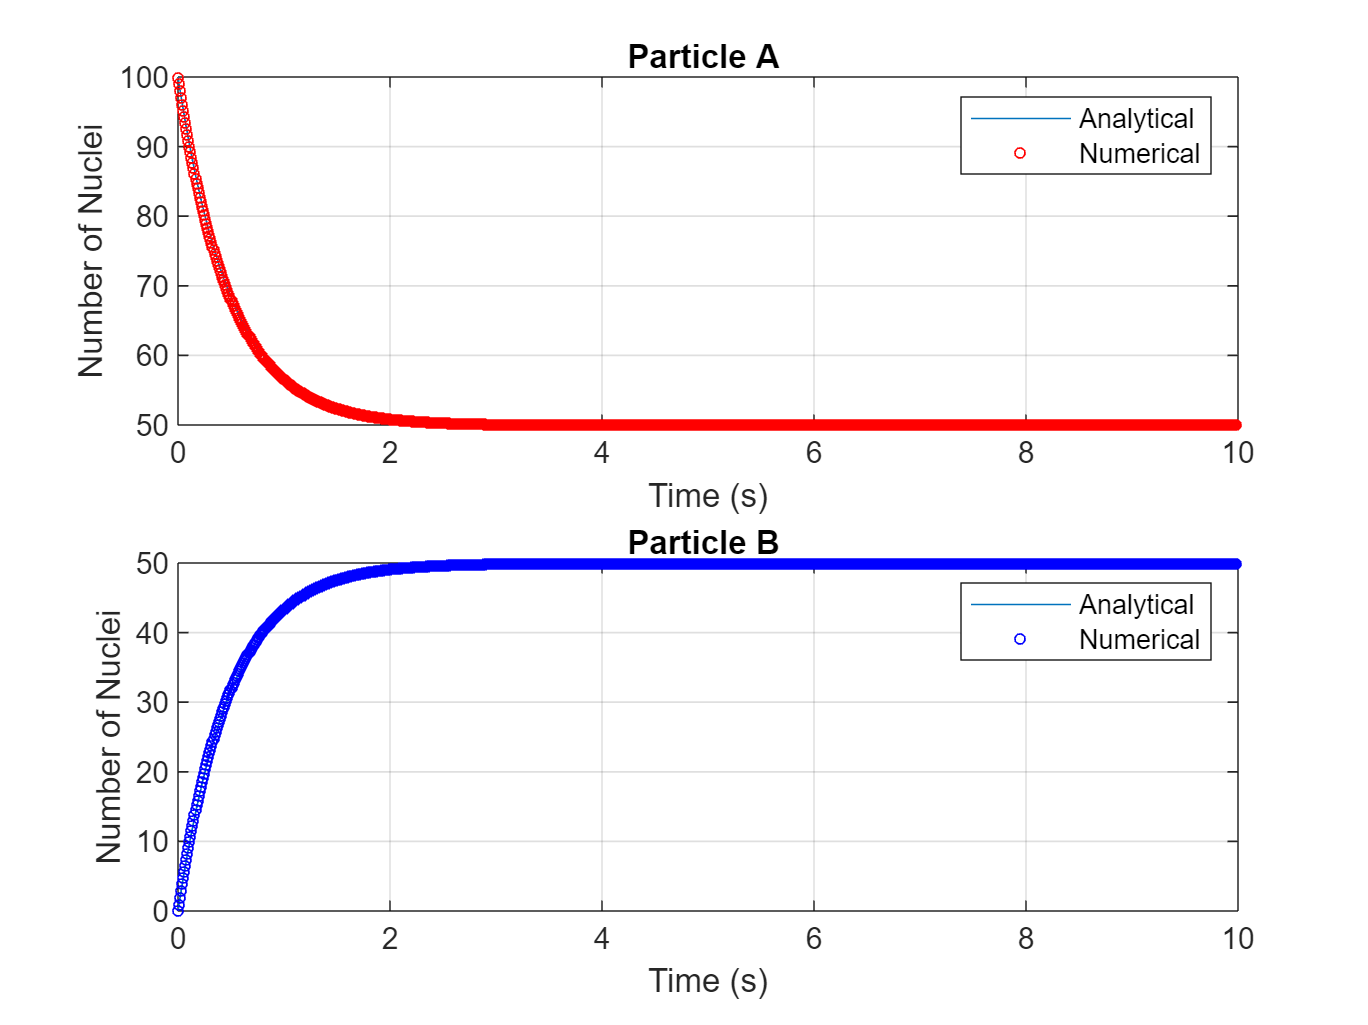

%  رسم نمودار مقایسه پاسخ تحلیلی و عددی
figure;
% N_A
subplot(2, 1, 1)
plot(t,y_A);
hold on
plot(t, N_A,'ro', 'MarkerSize', 3); 

xlabel('Time (s)'); 
ylabel('Number of Nuclei'); 
legend('Analytical', 'Numerical'); 
title('Particle A ')
grid on;

% N_B
subplot(2, 1, 2)
plot(t,y_B);
hold on; 
plot(t, N_B,'bo', 'MarkerSize', 3); 

xlabel('Time (s)'); 
ylabel('Number of Nuclei'); 
legend('Analytical', 'Numerical'); 
title('Particle B ')
grid on;